# Kalman Consensus Filter

## Setup

clear;
clc;
format short;

% Parameters
t = 1;                                                      % time step
itr = 100;                                                  % total time steps
number_of_sensors = 12;                                     % # sensors
consensus_terms = linspace(0,1,10);
epochs = length(consensus_terms);

% Data loading
load_data = false;                                          % false - generates new data
file_name = "data.mat";

if load_data
    if file_name == ""
        file = uigetfile;
        data = load(file);
    elseif isfile(file_name)
        data = load(file_name);
    else
        disp("The file does not exist, please select one");
        file = uigetfile;
        data = load(file);
    end
end

## Sensor Config

corner = [1,4,7,10];
edge_x = [5,6,11,12];
edge_y = [2,3,8,9];

% Sensor Network Configuration
no_of_neighbours = 5;
Neighbours = NaN(number_of_sensors,no_of_neighbours);
sen = linspace(1,12,12);

for c = 1:number_of_sensors
    j = NaN(1,5);
    % Before
    for k = 1:2
        if c-k < 1
            j(1,k) = sen(end + (c-k));
        else
            j(1,k) = sen(c-k);
        end
    end
    j(1,3) = c;
    for k = 1:2
        if c+k > number_of_sensors
                j(1,3+k) = sen((c+k) - number_of_sensors);
        else
            j(1,3+k) = sen(c+k);
        end
    end
    Neighbours(c,:) = j;
end

% Sensor noise
corner_noise = 2.0;                                 % Edit the sensor noise here
edge_x_noise = 2.0;
edge_y_noise = 2.0;

sensor_noise = NaN(number_of_sensors,1);

R = zeros(6,6,number_of_sensors);

% Measurement model
H_corner = NaN(2,6,4);
H_edge_x = NaN(2,6,4);
H_edge_y = NaN(2,6,4);

for c = 1:number_of_sensors
    if any(corner == c)
        sensor_noise(c,1) = corner_noise;
        row_ind = find(corner == c);
        H_corner(:,:,row_ind) = [1 0 0 0 0 0;
                                 0 0 0 1 0 0];
        R(:,:,c) = sensor_noise(c).^2 * eye(6,6);
    elseif any(edge_x == c)
        sensor_noise(c,1) = edge_x_noise;
        row_ind = find(edge_x == c);
        H_edge_x(:,:,row_ind) = [1 0 0 0 0 0;
                                 0 0 0 1 0 0];
        R(:,:,c) = sensor_noise(c).^2 * eye(6,6);
    elseif any(edge_y == c)
        sensor_noise(c,1) = edge_y_noise;
        row_ind = find(edge_y == c);
        H_edge_y(:,:,row_ind) = [1 0 0 0 0 0;
                                 0 0 0 1 0 0];
       R(:,:,c) = sensor_noise(c).^2 * eye(6,6);
    end
end

## Initialization

start_x = 0;
start_y = 0;

% Covariance
sig_x = 500;
sig_x_vel = 500;
sig_x_acc = 500;
sig_y = 500;
sig_y_vel = 500;
sig_y_acc = 500;

% Process Noise
random_acc_sig = 0.2; 

% Initial guess
init_x = [start_x 0 0 start_y 0 0]';

init_p = [sig_x 0 0 0 0 0;                          % We assume that the estimation errors in X and Y are not correlated
          0 sig_x_vel 0 0 0 0;
          0 0 sig_x_acc 0 0 0;
          0 0 0 sig_y 0 0;
          0 0 0 0 sig_y_vel 0;
          0 0 0 0 0 sig_y_acc];

% State transistion model
f = [1  t   0.5*t.^2    0   0   0;
     0  1   t   0   0   0;
     0  0   1   0   0   0;
     0  0   0   1   t   0.5*t.^2;
     0  0   0   0   1   t;
     0  0   0   0   0   1];

% Process noise
q = [t.^4/4 t.^3/2  t.^2/2  0   0   0;
     t.^3/2 t.^2/2  t   0   0   0;
     t.^2/2 t   1   0   0   0;
     0  0   0   t.^4/4  t.^3/2  t.^2/2;
     0  0   0   t.^3/2  t.^2/2  t;
     0  0   0   t.^2/2  t   1];

q = q * random_acc_sig.^2;

## Generate Sensor Value

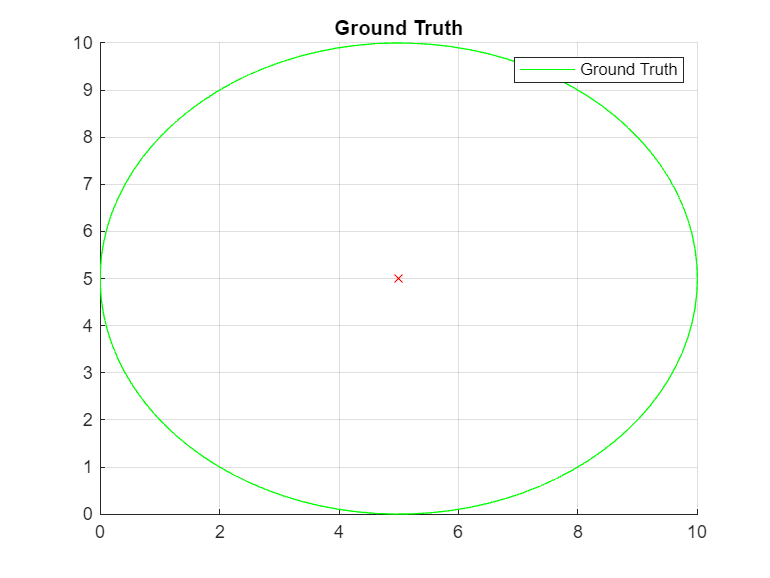

% circle data
radius = 5;
start_x = 5;
start_y = 5;

[true_x,true_y] = true_circle(start_x,start_y,radius,itr);

%==================================================
% To generate ground truth value
function [x,y] = true_circle(x,y,r,itr)
    th = linspace(0,2*pi,itr);
    x = r * cos(th) + x;
    y = r * sin(th) + y;
end

function O = gen_sens_val(true_x,true_y,sd)
    number_of_sensors = length(true_x);
    noise_raw_x = randn(1,number_of_sensors)*sd;
    noise_raw_y = rand(1,number_of_sensors)*sd;
    window_size = 20;
    b = ones(window_size,1)/window_size;
    a = 1;
    noise_filtered_x = filter(b, a, noise_raw_x);
    noise_filtered_y = filter(b, a, noise_raw_y);
    sens_x = (true_x + noise_filtered_x);
    sens_y = (true_y + noise_filtered_y);
    O = [sens_x;sens_y];
end
%==================================================

if ~load_data
    % To generate sensor data for the first time
    circle.id = 1;
    circle.start_x = start_x;
    circle.start_y = start_y;
    circle.radius = radius;
    circle.true_x = true_x;
    circle.true_y = true_y;
    
    z1 = gen_sens_val(true_x,true_y,sensor_noise(1));
    z2 = gen_sens_val(true_x,true_y,sensor_noise(2));
    z3 = gen_sens_val(true_x,true_y,sensor_noise(3));
    z4 = gen_sens_val(true_x,true_y,sensor_noise(4));
    z5 = gen_sens_val(true_x,true_y,sensor_noise(5));
    z6 = gen_sens_val(true_x,true_y,sensor_noise(6));
    z7 = gen_sens_val(true_x,true_y,sensor_noise(7));
    z8 = gen_sens_val(true_x,true_y,sensor_noise(8));
    z9 = gen_sens_val(true_x,true_y,sensor_noise(9));
    z10 = gen_sens_val(true_x,true_y,sensor_noise(10));
    z11 = gen_sens_val(true_x,true_y,sensor_noise(11));
    z12 = gen_sens_val(true_x,true_y,sensor_noise(12));
    
    circle.sensor1.x = z1(1,:);
    circle.sensor1.y = z1(2,:);
    
    circle.sensor2.x = z2(1,:);
    circle.sensor2.y = z2(2,:);
    
    circle.sensor3.x = z3(1,:);
    circle.sensor3.y = z3(2,:);
    
    circle.sensor4.x = z4(1,:);
    circle.sensor4.y = z4(2,:);
    
    circle.sensor5.x = z5(1,:);
    circle.sensor5.y = z5(2,:);
    
    circle.sensor6.x = z6(1,:);
    circle.sensor6.y = z6(2,:);
    
    circle.sensor7.x = z7(1,:);
    circle.sensor7.y = z7(2,:);
    
    circle.sensor8.x = z8(1,:);
    circle.sensor8.y = z8(2,:);
    
    circle.sensor9.x = z9(1,:);
    circle.sensor9.y = z9(2,:);
    
    circle.sensor10.x = z10(1,:);
    circle.sensor10.y = z10(2,:);
    
    circle.sensor11.x = z11(1,:);
    circle.sensor11.y = z11(2,:);
    
    circle.sensor12.x = z12(1,:);
    circle.sensor12.y = z12(2,:);
    
    data = circle;
    
    if isfile(file_name)
        save("data.mat","circle","-append");
    else
        save("data.mat","circle");
    end

    % Plot ground truth
    figure;
    grid on;
    hold on;
    plot(true_x,true_y,'g',"DisplayName","Ground Truth");
    plot(start_x,start_y,'r', "Marker","x");
    title("Ground Truth");
    legend("Ground Truth");
end

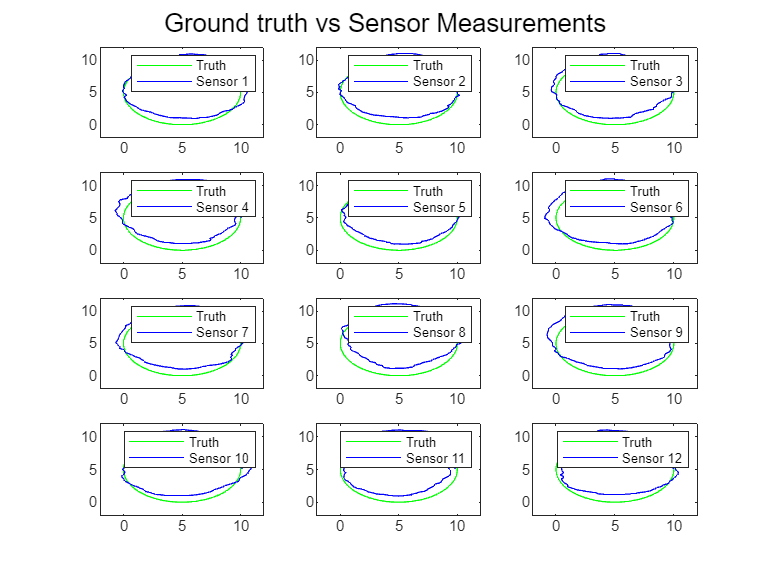

%==================================================
% Load data from data.mat
%==================================================

if ~load_data
    data.circle = circle;
else
    data = load(file_name);
end

% load ground truth
true_x = data.circle.true_x(1:itr);
true_y = data.circle.true_y(1:itr);

% load sensor data
Z = NaN(2,number_of_sensors,itr);

Z(1,1,:) = data.circle.sensor1.x(1:itr);
Z(2,1,:) = data.circle.sensor1.y(1:itr);

Z(1,2,:) = data.circle.sensor2.x(1:itr);
Z(2,2,:) = data.circle.sensor2.y(1:itr);

Z(1,3,:) = data.circle.sensor3.x(1:itr);
Z(2,3,:) = data.circle.sensor3.y(1:itr);

Z(1,4,:) = data.circle.sensor4.x(1:itr);
Z(2,4,:) = data.circle.sensor4.y(1:itr);

Z(1,5,:) = data.circle.sensor5.x(1:itr);
Z(2,5,:) = data.circle.sensor5.y(1:itr);

Z(1,6,:) = data.circle.sensor6.x(1:itr);
Z(2,6,:) = data.circle.sensor6.y(1:itr);

Z(1,7,:) = data.circle.sensor7.x(1:itr);
Z(2,7,:) = data.circle.sensor7.y(1:itr);

Z(1,8,:) = data.circle.sensor8.x(1:itr);
Z(2,8,:) = data.circle.sensor8.y(1:itr);

Z(1,9,:) = data.circle.sensor9.x(1:itr);
Z(2,9,:) = data.circle.sensor9.y(1:itr);

Z(1,10,:) = data.circle.sensor10.x(1:itr);
Z(2,10,:) = data.circle.sensor10.y(1:itr);

Z(1,11,:) = data.circle.sensor11.x(1:itr);
Z(2,11,:) = data.circle.sensor11.y(1:itr);

Z(1,12,:) = data.circle.sensor12.x(1:itr);
Z(2,12,:) = data.circle.sensor12.y(1:itr);

% plot ground truth vs sensor measurements
figure;
for c = 1:number_of_sensors
    subplot(4,3,c);
    plot(true_x,true_y,'g',"DisplayName","Truth");
    hold on;
    px = reshape(Z(1,c,:),[1,itr]);
    py = reshape(Z(2,c,:),[1,itr]);
    str = "Sensor "+c;
    plot(px,py,'b',"DisplayName",str);
    xlim([-2,12]);
    ylim([-2,12]);
    legend(["Truth",str]);
end
sgtitle("Ground truth vs Sensor Measurements");

Sensor_Error = NaN(1,number_of_sensors);
for n = 1:number_of_sensors
    summ = 0;
    for k = 1:itr
        sqr_error = (Z(1,n,k) - true_x(1,k))^2 + (Z(2,n,k) - true_y(1,k))^2;
        summ = summ + sqr_error;
    end
    Sensor_Error(:,n) = summ / itr;
end

## Initialize Algorithm

% Prediction Step
x_1 = f*init_x;
p_1 = f*init_p*f' + q;

% Storage initialization
X_Est = NaN(6,number_of_sensors,itr,epochs);                   %[x,#sensors,iteration,epoch]
P_Est = NaN(6,6,number_of_sensors,itr,epochs);

X_Pred = NaN(6,number_of_sensors,itr+1,epochs);
P_Pred = NaN(6,6,number_of_sensors,itr+1,epochs);

M_I = NaN(6,6,number_of_sensors,itr,epochs);

consensus_disagreement = NaN(2,itr,epochs);

con_diff = NaN(2,number_of_sensors,itr);

for c = 1:number_of_sensors
    X_Pred(:,c,1,1) = x_1;
    P_Pred(:,:,c,1,1) = p_1;
end

MSE = NaN(1,number_of_sensors,epochs);

## Algorithm

for e = 1:epochs  % length(eps)
    for i = 1:itr
        % At each iterations
        for n = 1:number_of_sensors
            % for every sensor
            msg.y_n = zeros(6,no_of_neighbours);           % measurement % number_of_sensors-1 because each sensor can have two neighboring sensor + itself
            msg.s_n = zeros(6,6,no_of_neighbours);         % covariance
            msg.x_n = zeros(2,no_of_neighbours);           % state estimate
            for nei = 1:no_of_neighbours
                % for every neighbour
                j = Neighbours(n,nei);
                r_nei = R(:,:,j);
                z_nei = [Z(1,j,i) 0 0 Z(2,j,i) 0 0];
                
                if any(corner == j)
                    row_ind = find(corner == j);
                    h_nei = H_corner(:,:,row_ind);
                    y_n = h_nei/r_nei * z_nei';
                    msg.y_n(:,nei) = [y_n(1,1) 0 0 y_n(2,1) 0 0];
                    s_n = (h_nei/r_nei * h_nei');
                    s1 = s_n(1,1) * eye(3,3);
                    s2 = s_n(2,2) * eye(3,3);
                    s3 = eye(6,6);
                    s3(1:3,1:3) = s1;
                    s3(4:6,4:6) = s2;
                    msg.s_n(:,:,nei) = s3;
                elseif any(edge_x == j)
                    row_ind = find(edge_x == j);
                    h_nei = H_edge_x(:,:,row_ind);
                    y_n = h_nei/r_nei * z_nei';
                    msg.y_n(:,nei) = [y_n(1,1) 0 0 y_n(2,1) 0 0];
                    % msg.y_n(:,nei) = [y_n 0 0 0 0 0];
                    % msg.s_n(:,:,nei) = (h_nei/r_nei * h_nei') * eye(6,6);
                    s_n = (h_nei/r_nei * h_nei');
                    s1 = s_n(1,1) * eye(3,3);
                    s2 = s_n(2,2) * eye(3,3);
                    s3 = eye(6,6);
                    s3(1:3,1:3) = s1;
                    s3(4:6,4:6) = s2;
                    msg.s_n(:,:,nei) = s3;
                elseif any(edge_y == j)
                    row_ind = find(edge_y == j);
                    h_nei = H_edge_y(:,:,row_ind);
                    y_n = h_nei/r_nei * z_nei';
                    msg.y_n(:,nei) = [y_n(1,1) 0 0 y_n(2,1) 0 0];
                    s_n = (h_nei/r_nei * h_nei');
                    s1 = s_n(1,1) * eye(3,3);
                    s2 = s_n(2,2) * eye(3,3);
                    s3 = eye(6,6);
                    s3(1:3,1:3) = s1;
                    s3(4:6,4:6) = s2;
                    msg.s_n(:,:,nei) = s3;
                    % msg.y_n(:,nei) = [0 0 0 y_n 0 0];
                    % msg.s_n(:,:,nei) = (h_nei/r_nei * h_nei') * eye(6,6);
                end
                msg.x_n(:,nei) = [X_Pred(1,j,i);X_Pred(4,j,i)];
            end
    
            % current state estimate
            Y_n = zeros(6,1);
            S_n = zeros(6,6);
            x_diff_sum = 0;
            for m = 1:no_of_neighbours
                Y_n = Y_n + msg.y_n(:,m);
                S_n = S_n + msg.s_n(:,:,m);
                if m ~= 3
                    x_diff_sum = x_diff_sum + (msg.x_n(:,m) - msg.x_n(:,3));
                end
            end

            x_diff_sum = [x_diff_sum(1,1) 0 0 x_diff_sum(2,1) 0 0]';
    
            M_i = inv(inv(P_Pred(:,:,n,i)) + S_n);
            M_I(:,:,n,i,e) = M_i;
            x_p = X_Pred(:,n,i);
            innovation = Y_n - (S_n*x_p);
            c_t = (consensus_terms(e)*M_i*x_diff_sum);
            x_est = x_p + (M_i*innovation) + c_t;
    
            % Update state
            p_next = f*M_i*f' + q;
            x_next = f*x_est;
    
            % Store values
            X_Est(:,n,i,e) = x_est;
            X_Pred(:,n,i+1,e) = x_next;
            P_Pred(:,:,n,i+1,e) = p_next;
        end   
    end

    % MSE calculation
    for nn = 1:number_of_sensors
        summ = 0;
        for c = 1:itr
            sqr_error = (X_Est(1,nn,c,e) - true_x(1,c))^2 + (X_Est(4,nn,c,e) - true_y(1,c))^2;
            summ = summ + sqr_error;
        end
        MSE(:,nn,e) = summ / itr;
    end
end

## Visualization

% Find the best consensus term
smallest = inf;
smallest_ind = -1;
epoch_MSE = NaN(1,epochs);
for i = 1:epochs
    summ = sum(MSE(:,12,i));
    summ = summ / epochs;
    epoch_MSE(:,i) = summ;
    % disp(summ);
    if summ < smallest
        smallest = summ;
        smallest_ind = i;
    end
end

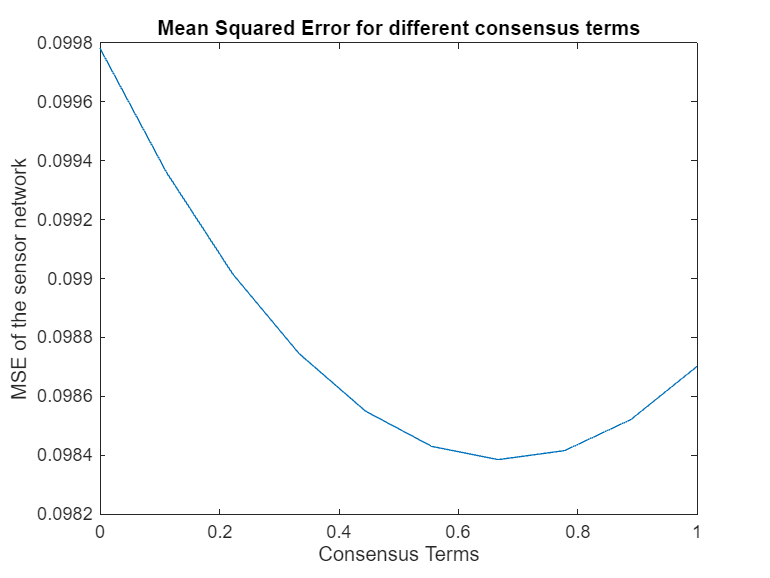

% MSE for different consensus terms
figure;
plot(consensus_terms,epoch_MSE);
xlabel("Consensus Terms");
ylabel("MSE of the sensor network");
title("Mean Squared Error for different consensus terms");

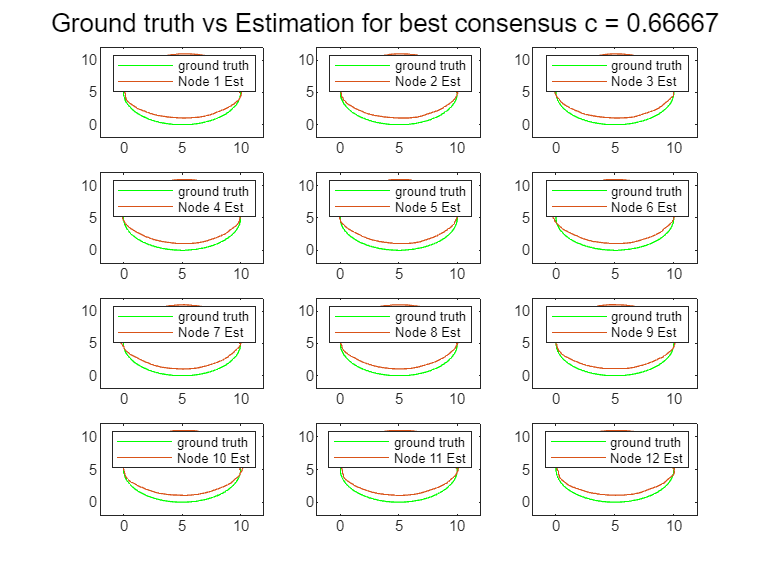

% Estimation for the best consensus term
figure;
ee = smallest_ind;
for c = 1:number_of_sensors
    subplot(4,3,c);
    plot(true_x,true_y,'g',"DisplayName","ground truth");
    hold on;
    px = reshape(X_Est(1,c,:,ee),[1,itr]);
    py = reshape(X_Est(4,c,:,ee),[1,itr]);
    str = "Node "+c+" Est";
    plot(px,py,"DisplayName",str);
    xlim([-2,12]);
    ylim([-2,12]);
    legend(["ground truth",str]);
end
sgtitle("Ground truth vs Estimation for best consensus c = " + consensus_terms(smallest_ind));

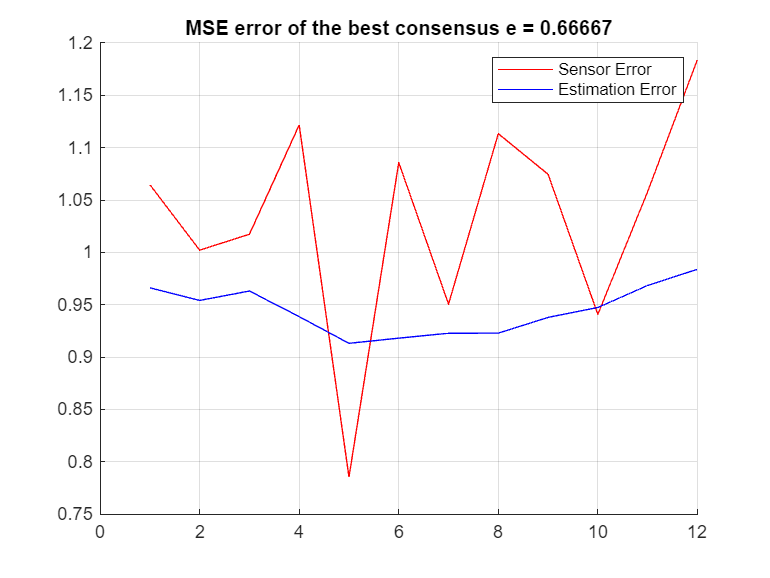

% MSE for the best consensus estimate
figure;
hold on;
grid on;
plot(Sensor_Error(:,:),'r',"DisplayName","Sensor Error");
val = reshape(MSE(:,:,smallest_ind),[1,12]);
plot(val,'b',"DisplayName","Estimation Error");
legend(["Sensor Error", "Estimation Error"]);
title("MSE error of the best consensus e = " + consensus_terms(smallest_ind));

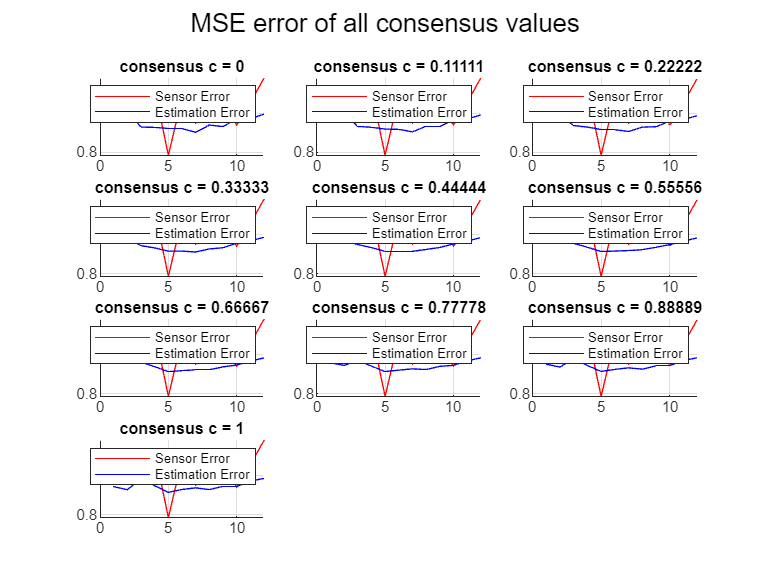

% MSE of all consensus terms
figure;
title("Sensor MSE vs Estimation MSE at different Consensus terms");
for c = 1:epochs
    subplot(4,3,c);
    grid on;
    hold on;
    str = "Sensor Error";
    plot(Sensor_Error(:,:),'r',"DisplayName",str);
    val = reshape(MSE(:,:,c),[1,12]);
    str1 = "Estimation Error";
    plot(val,'b',"DisplayName",str1);
    legend([str,str1]);
    title("consensus c = " + consensus_terms(c));
end
sgtitle("MSE error of all consensus values");